# Load documents

clc
close all;
clear all;
folder = 'C:\Users\wenhanzhang\MATLAB\Projects\FDA_window_comparison';
fullMatFileName = fullfile(folder,'WiFi_bits1.mat');
if ~exist(fullMatFileName, 'file')
  message = sprintf('%s does not exist', fullMatFileName);
  uiwait(warndlg(message));
else
  WaveStruct = load(fullMatFileName);
end
wifi = WaveStruct.waveStruct.waveform;
fullMatFileName = fullfile(folder,'bits1.mat');
bits = load(fullMatFileName).bits;

## DSSS

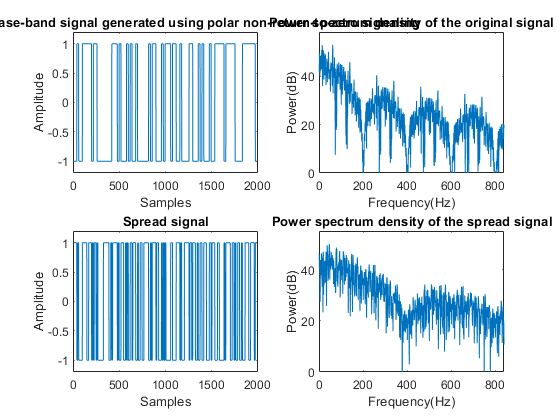

R = length(bits);               % The length of the bit stream.
S = 20;                         % Bit duration(each bit is represented with 
                                % S samples of the waveform used in signaling.
bit_stream = bits;              % A Randomley Generated Bit Stream.    
bits_wifi = zeros(1,S*R);       % Predefinition of the Base-band wifi signal.

% Generating the PAM signal using Polar Non-Return-to-Zero signaling. Every
% S samples correspond to one bit.
for i = 1:R
    if bit_stream(1,i)== 0
        bits_wifi(1+(i-1)*S : i*S) = -1;
    else
        bits_wifi(1+(i-1)*S : i*S) =  1;
    end
end

figure
subplot(2,2,1)
plot(bits_wifi);
axis([-1 S*R+10 -1.2 1.2]);
title('The original base-band signal generated using polar non-return-to-zero signaling');
xlabel('Samples')
ylabel('Amplitude')

% As we know, The Fourier transform of the autocorrelation function results 
% to the Power Spectral Density function.
z = 10*log10(abs(fft(xcorr(bits_wifi)))); % PSD of the PAM signal.
subplot(2,2,2);
plot(z);
axis([0 840 0 1.1*max(z)]);
title('Power spectrum density of the original signal');
xlabel('Frequency(Hz)')
ylabel('Power(dB)')

% Generating the pseudo random SEQUENCE for spreading.
pn_seq = round(rand(1,100));

% Generating the pseudo random SIGNAL for spreading.
pn_sig_txr1 = zeros(1,S*R);   % Pseudo Noise signal in the trx.
for i = 1:100
    if pn_seq(1,i)==0
        pn_sig_trx1(1+(i-1)*S*R/(length(pn_seq)):i*S*R/(length(pn_seq))) = -1;
    else
        pn_sig_trx1(1+(i-1)*S*R/(length(pn_seq)):i*S*R/(length(pn_seq))) =  1;
    end  
end

K = round(rand(1,1)*S*R);
pn_sig_trx = [pn_sig_trx1(K:end) pn_sig_trx1(1:K-1)];
% Spreading of sequence
spreaded_sig = bits_wifi .* pn_sig_trx;
subplot(2,2,3);
plot(spreaded_sig);
axis([-1 S*R+10 -1.2 1.2]);
title('Spread signal');
xlabel('Samples')
ylabel('Amplitude')

z = 10*log10(abs(fft(xcorr(spreaded_sig))));   % PSD of the spreaded signal.
subplot(2,2,4);
plot(z);
axis([0 840 0 1.1*max(z)]);
title('Power spectrum density of the spread signal');
xlabel('Frequency(Hz)')
ylabel('Power(dB)')

## Binary signal generation

bits_wifi_binary = zeros(1, length(bits_wifi));
for i = 1:length(bits_wifi)
    if bits_wifi(1,i)== -1
        bits_wifi_binary(1, i) = 0;
    else
        bits_wifi_binary(1, i) = 1;
    end
end

spreaded_sig_binary = zeros(1, length(spreaded_sig));
for i = 1:length(spreaded_sig)
    if spreaded_sig(1,i)== -1
        spreaded_sig_binary(1, i) = 0;
    else
        spreaded_sig_binary(1, i) = 1;
    end
end

## QPSK

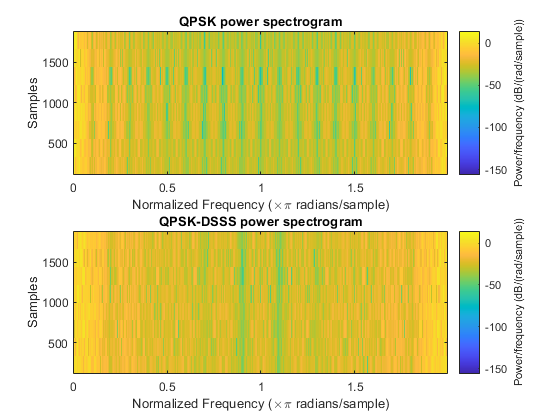

figure
y_q1 = pskmod(bits_wifi_binary, 4);
subplot(2,1,1)
spectrogram(y_q1);
title('QPSK power spectrogram');
y_q2 = pskmod(spreaded_sig_binary, 4);
subplot(2,1,2)
spectrogram(y_q2);
title('QPSK-DSSS power spectrogram');

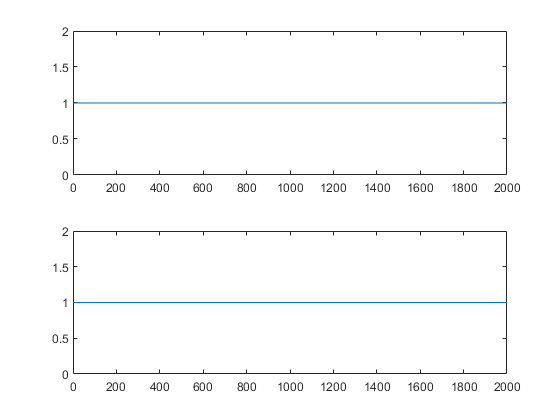


figure
subplot(2,1,1)
plot(abs(y_q1))
subplot(2,1,2)
plot(abs(y_q2))

## BPSK

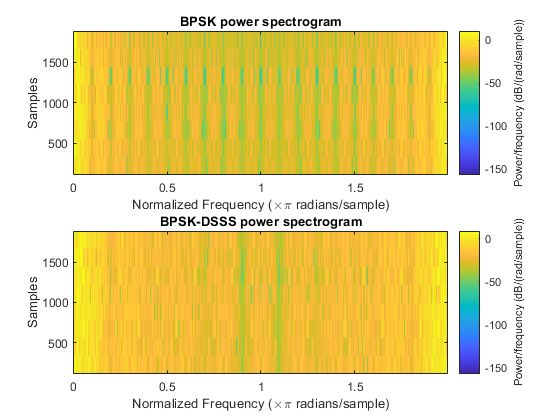

figure
y_b1 = pskmod(bits_wifi_binary, 2);
subplot(2,1,1)
spectrogram(y_b1);
title('BPSK power spectrogram');
y_b2 = pskmod(spreaded_sig_binary, 2);
subplot(2,1,2)
spectrogram(y_b2);
title('BPSK-DSSS power spectrogram');

## 16QAM

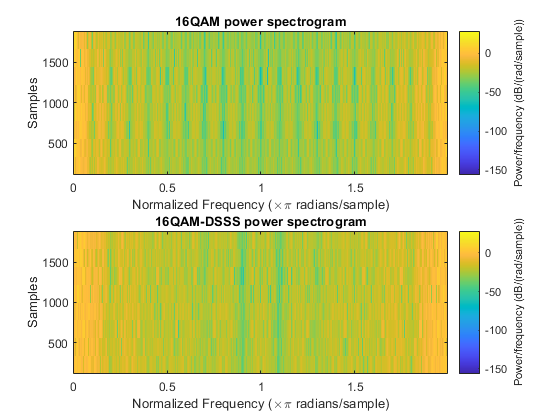

figure
y_16qa1 = qammod(bits_wifi_binary, 16);
subplot(2,1,1)
spectrogram(y_16qa1);
title('16QAM power spectrogram');
y_16qa2 = qammod(spreaded_sig_binary, 16);
subplot(2,1,2)
spectrogram(y_16qa2);
title('16QAM-DSSS power spectrogram');

## 64QAM

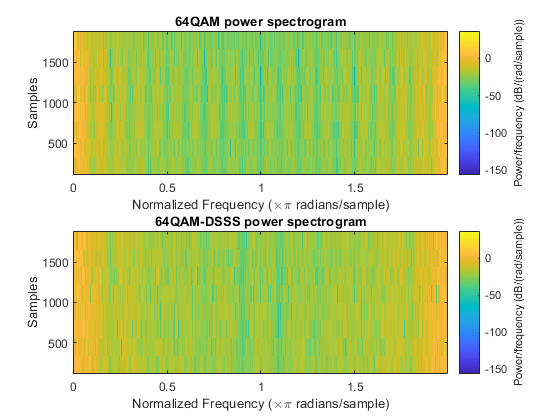

figure
y_64qa1 = qammod(bits_wifi_binary, 64);
subplot(2,1,1)
spectrogram(y_64qa1);
title('64QAM power spectrogram');
y_64qa2 = qammod(spreaded_sig_binary, 64);
subplot(2,1,2)
spectrogram(y_64qa2);
title('64QAM-DSSS power spectrogram');

## Power density calculation

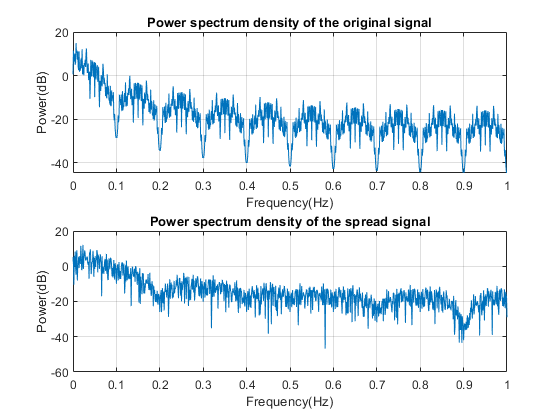

figure
subplot(2,1,1)
periodogram(bits_wifi,rectwin(length(bits_wifi)),length(bits_wifi));
title('Power spectrum density of the original signal');
xlabel('Frequency(Hz)')
ylabel('Power(dB)')
subplot(2,1,2);
periodogram(spreaded_sig,rectwin(length(spreaded_sig)),length(spreaded_sig));
title('Power spectrum density of the spread signal');
xlabel('Frequency(Hz)')
ylabel('Power(dB)')

## Bits comparison

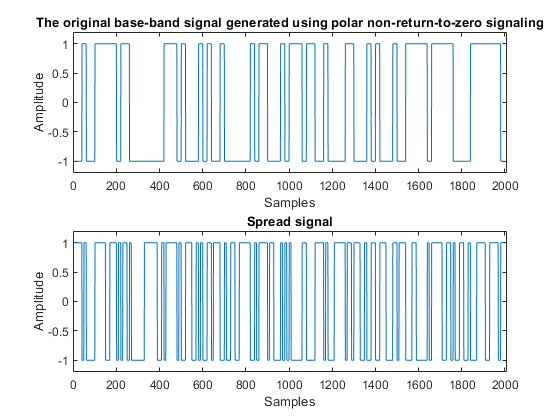

figure
subplot(2,1,1)
plot(bits_wifi);
axis([-1 S*R+10 -1.2 1.2]);
title('The original base-band signal generated using polar non-return-to-zero signaling');
xlabel('Samples')
ylabel('Amplitude')
% Spreading of sequence
subplot(2,1,2)
plot(spreaded_sig);
axis([-1 S*R+10 -1.2 1.2]);
title('Spread signal');
xlabel('Samples')
ylabel('Amplitude')